# Region-of-Interest (ROI)

*Please contact Ted (huppert1@pitt.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

This example show how to analyze using ROI

clear all
clc

load  AnalyzIR_Dataset1.mat

demo = readtable('/Users/hendriksantosa/Library/CloudStorage/OneDrive-UniversityofPittsburgh/NIRS_Summer_Course/Presentations/Day2/TableDemographics.xlsx', 'Format', 'auto');

job = nirs.modules.AddDemographics;
job.allowMissing = true;
job.demoTable=demo;
job.varToMatch='subject';
raw = job.run(raw);

% Basic Pipelines
job = nirs.modules.RenameStims();
job.listOfChanges = {'A',  'TaskA'; 'B', 'TaskB'};
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.Resample(job);
job.Fs = 1; %for speed
job = nirs.modules.BeerLambertLaw(job);
Hb = job.run(raw);

% First Level
job = nirs.modules.GLM();
Stats = job.run(Hb);

......................................................................Finished    1 of   68.
......................................................................Finished    2 of   68.
......................................................................Finished    3 of   68.
......................................................................Finished    4 of   68.
......................................................................Finished    5 of   68.
......................................................................Finished    6 of   68.
......................................................................Finished    7 of   68.
......................................................................Finished    8 of   68.
......................................................................Finished    9 of   68.
......................................................................Finished   10 of   68.
......................................................................

disp('This process takes about 1 min')

This process takes about 1 min



% Second Level
job=nirs.modules.MixedEffects;
job.formula='beta ~ -1  + cond + cond:ADHD + (1|AgeMonths) + (1|Sex) + (1|HeadSize)'; %continuous
job.robust=true;
job.include_diagnostics = true; %This is need to plot the scatter plot
Group1 = job.run(Stats);  

% Let's devide this probe into 5 region
% Region1: Any probe connect to S1 and S2
% Region2: Any probe connect to D3
% Region3: Any probe connect to S7 and S8
% Region4: Any probe connect to S9 and S10
% Region5: Any probe connect to S12 and D11

MeasList = [1 NaN; 2 NaN];
Region{1} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [NaN 3];
Region{2} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [7 NaN; 8 NaN];
Region{3} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [9 NaN; 10 NaN];
Region{4} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [12 NaN; NaN 11];
Region{5} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});

% This example to do the ROI in group level
[ROIGrouptable, ROIGroupstats] = nirs.util.roiAverage(Group1,Region,{'Region1','Region2','Region3','Region4','Region5'});
ROIGroupstats.probe.link

ans = 10×2 table
        ROI         type  
    ___________    _______

    {'Region1'}    {'hbo'}
    {'Region1'}    {'hbr'}
    {'Region2'}    {'hbo'}
    {'Region2'}    {'hbr'}
    {'Region3'}    {'hbo'}
    {'Region3'}    {'hbr'}
    {'Region4'}    {'hbo'}
    {'Region4'}    {'hbr'}
    {'Region5'}    {'hbo'}
    {'Region5'}    {'hbr'}


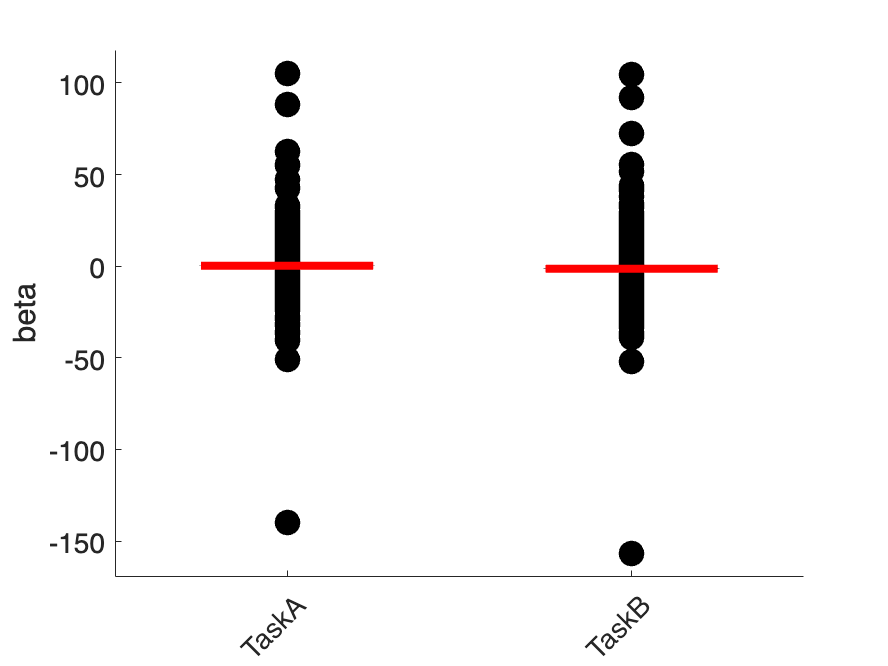

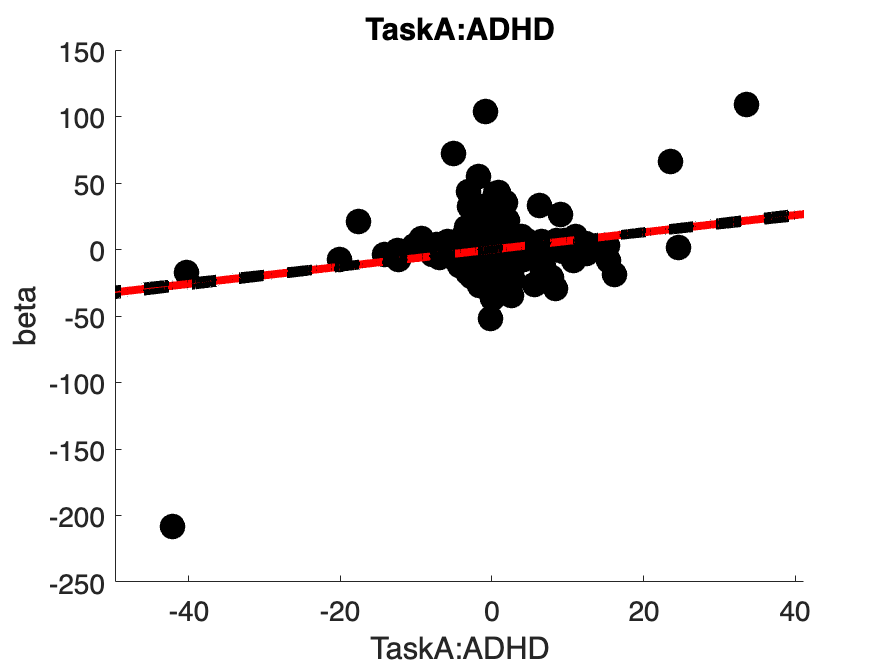

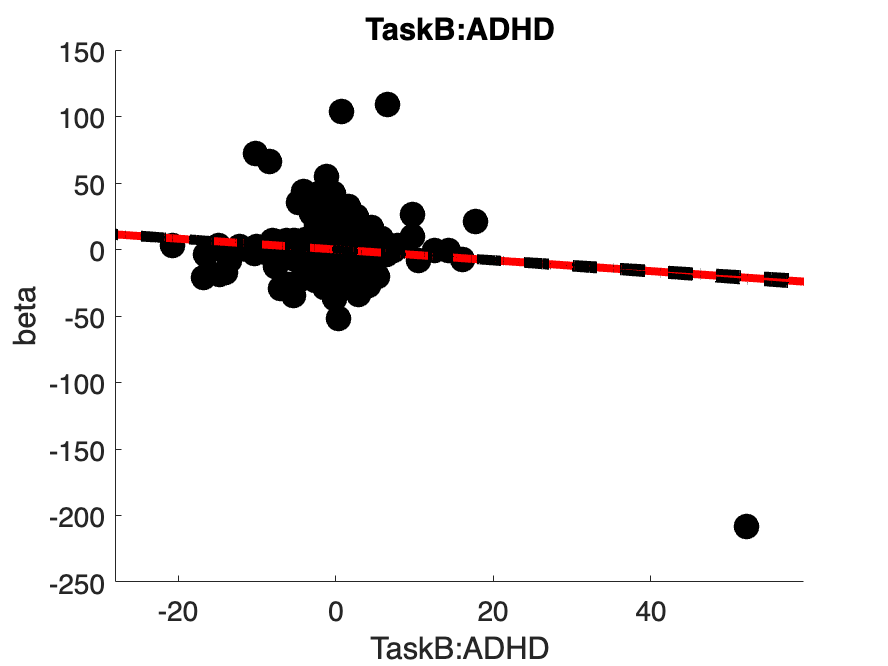

% In the table, you will see the group stats in 5 regions

%Let's say that you want to see the scatter plot from Region 3 for hbo
ROIGroupstats.scatterplot(5, 0.95, true) %Plot channel 1 (hbo): see Group1.probe.link

**Region of Interest (in hb data and stats)**

There are many ways to analyze in ROI:

- ROI in hb data: We can see the time series of that ROI results

- ROI after the first level

- ROI in the group level


%There are many option to do the ROI
% ROI in hb data: We can see the time series in that ROI
% ROI after the first level
% ROI in the group level (done)

% Let's see the ROI in the hb data
ROIhb = nirs.util.roiAverage(Hb,Region,{'Region1','Region2','Region3','Region4','Region5'});
%Check this: 
ROIhb(1).probe.link

ans = 10×2 table
        ROI         type  
    ___________    _______

    {'Region1'}    {'hbo'}
    {'Region1'}    {'hbr'}
    {'Region2'}    {'hbo'}
    {'Region2'}    {'hbr'}
    {'Region3'}    {'hbo'}
    {'Region3'}    {'hbr'}
    {'Region4'}    {'hbo'}
    {'Region4'}    {'hbr'}
    {'Region5'}    {'hbo'}
    {'Region5'}    {'hbr'}


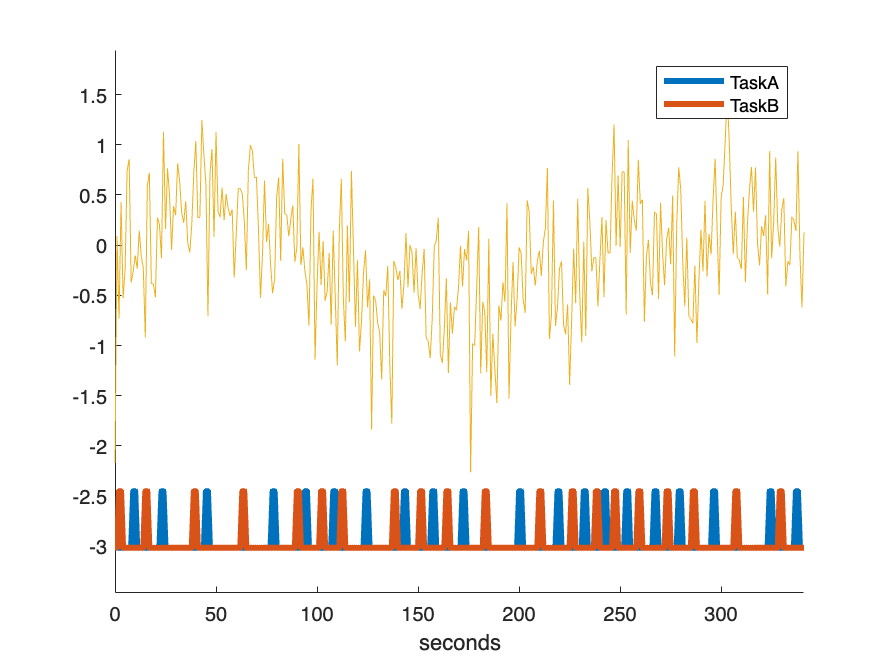

%You will see, this variable only has 10 data (5 regions X hb)
figure; ROIhb(10).draw(5) %hbo data from subject 10, region 3

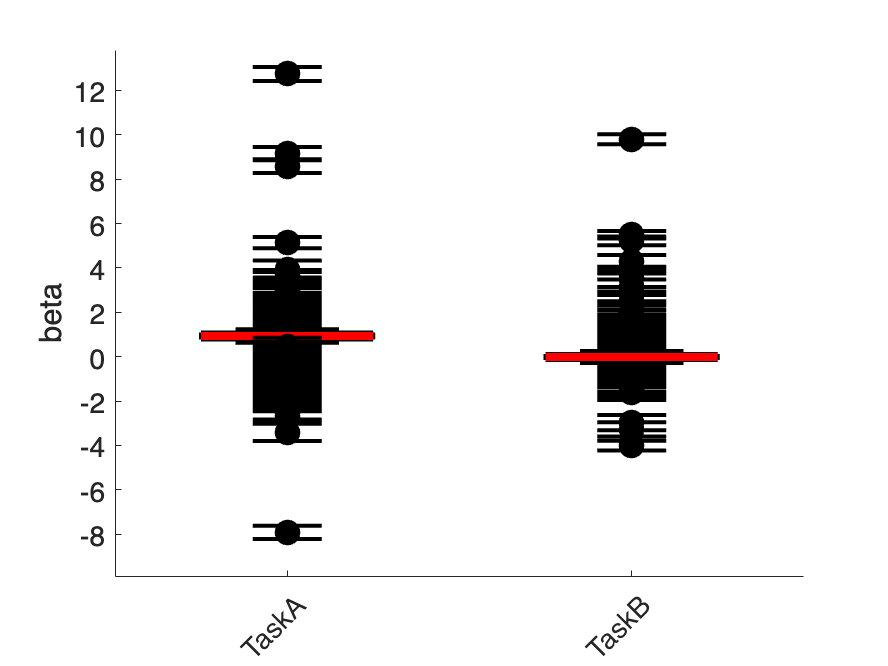

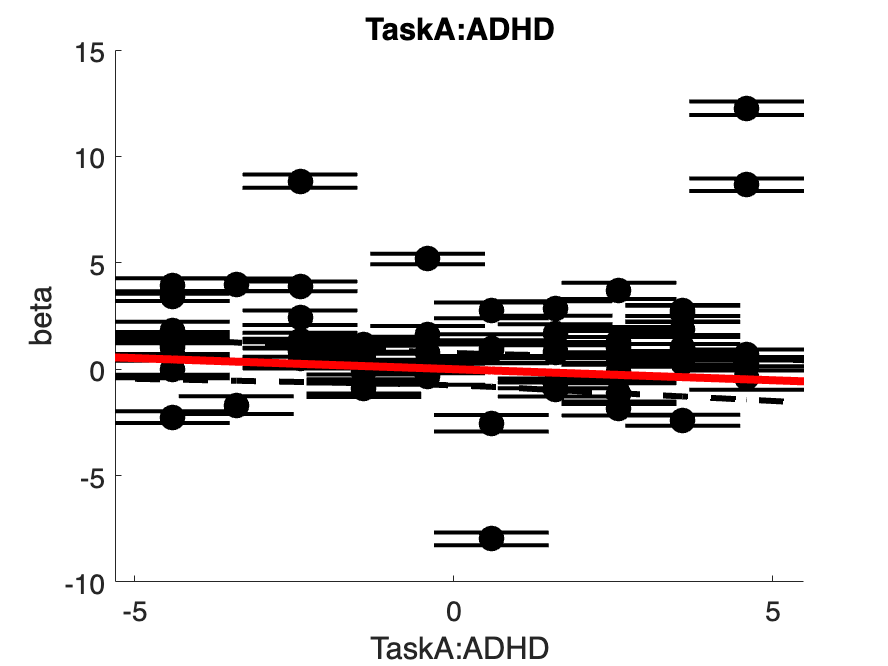

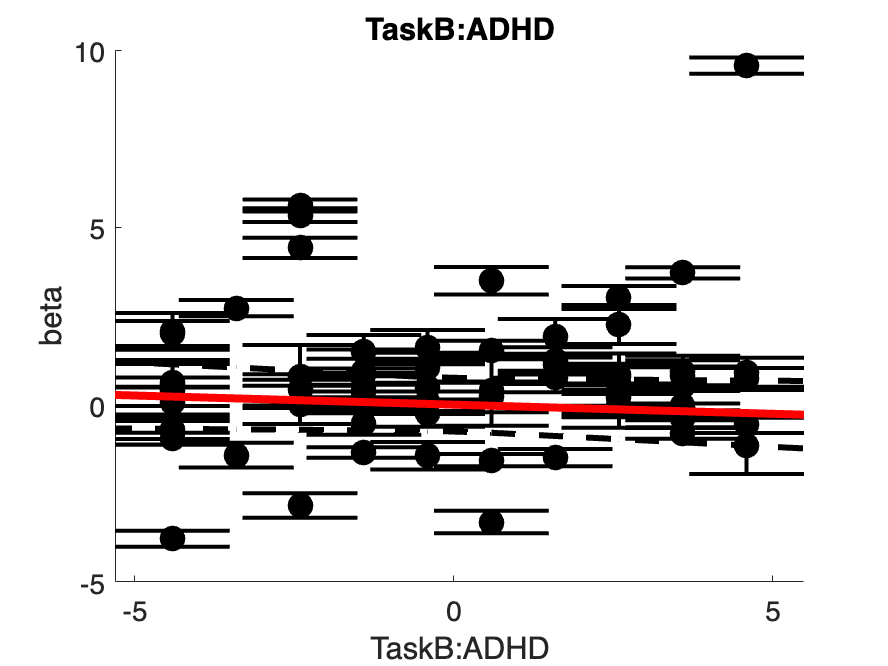


% Then, after this, you can run the first level, then the group level


% New function: ROI from tstat
roitbl=nirs.util.roi_from_tstat(Group1,{'TaskA:ADHD','TaskB:ADHD'});
roitbl.weight(roitbl.weight<0)=0;
[~,roi]=nirs.util.roiAverage(Stats,roitbl);

job=nirs.modules.MixedEffects;
job.formula='beta ~ -1  + cond + cond:ADHD + (1|AgeMonths) + (1|Sex) + (1|HeadSize)'; %continuous
job.robust=true;
job.include_diagnostics = true;
Group1roi = job.run(roi);  %only 1 roi average from that tstat

Group1roi.scatterplot(1, 0.95, true) %hbo data for TaskA:ADHD